clc; close all; clear

m=5;
b=0.2;
A=[0 1 0 0;
   0 -b/m 0 0;
    0 0 0 1;
    0 0 0 -b/m]

A =          0    1.0000         0         0
         0   -0.0400         0         0
         0         0         0    1.0000
         0         0         0   -0.0400


B=[0 0; 
    1/m 0; 
    0 0;
    0 1/m]

B =          0         0
    0.2000         0
         0         0
         0    0.2000


C=[1 0 0 0;
    0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D=zeros(2)

D =      0     0
     0     0


Gss=ss(A,B,C,D);
G=tf(Gss)


G =
 
  From input 1 to output...
           0.2
   1:  ------------
       s^2 + 0.04 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
           0.2
   2:  ------------
       s^2 + 0.04 s
 
Continuous-time transfer function.


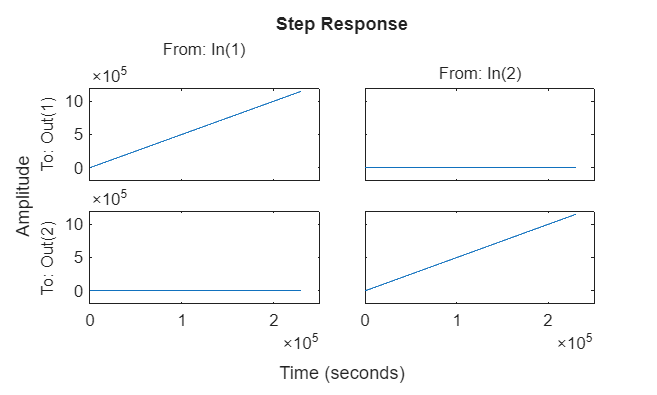

step(G)

%%
T11=25;
T22=25;
s=tf('s')


s =
 
  s
 
Continuous-time transfer function.


Gl=[1/(T11*s) 0; 0 1/(T22*s)];
Gc=inv(G)*Gl;
Gc=minreal(Gc)


Gc =
 
  From input 1 to output...
   1:  0.2 s + 0.008
 
   2:  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2 s + 0.008
 
Continuous-time transfer function.


Gt=feedback(Gl, eye(2))


Gt =
 
  From input 1 to output...
         0.04
   1:  --------
       s + 0.04
 
   2:  0
 
  From input 2 to output...
   1:  0
 
         0.04
   2:  --------
       s + 0.04
 
Continuous-time transfer function.


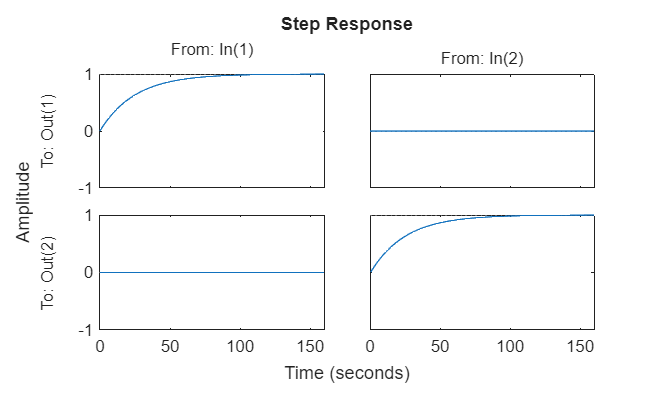

step(Gt)

info=stepinfo(Gt)

info = 2×2 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


info(1,1)

ans = struct with fields:
         RiseTime: 54.9252
    TransientTime: 97.8019
     SettlingTime: 97.8019
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 183.0555


info(2,2)

ans = struct with fields:
         RiseTime: 54.9252
    TransientTime: 97.8019
     SettlingTime: 97.8019
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 183.0555
